## How to read a GQRX recording file (raw data).

GQRX saves IQ recordings as RAW files, containing the samples as floats and using the sample rate listed on the end of the filename.

Data Format:

32 bit float LE (little endian)

You can load the GQRX IQ recording on MATLAB.

#### Example

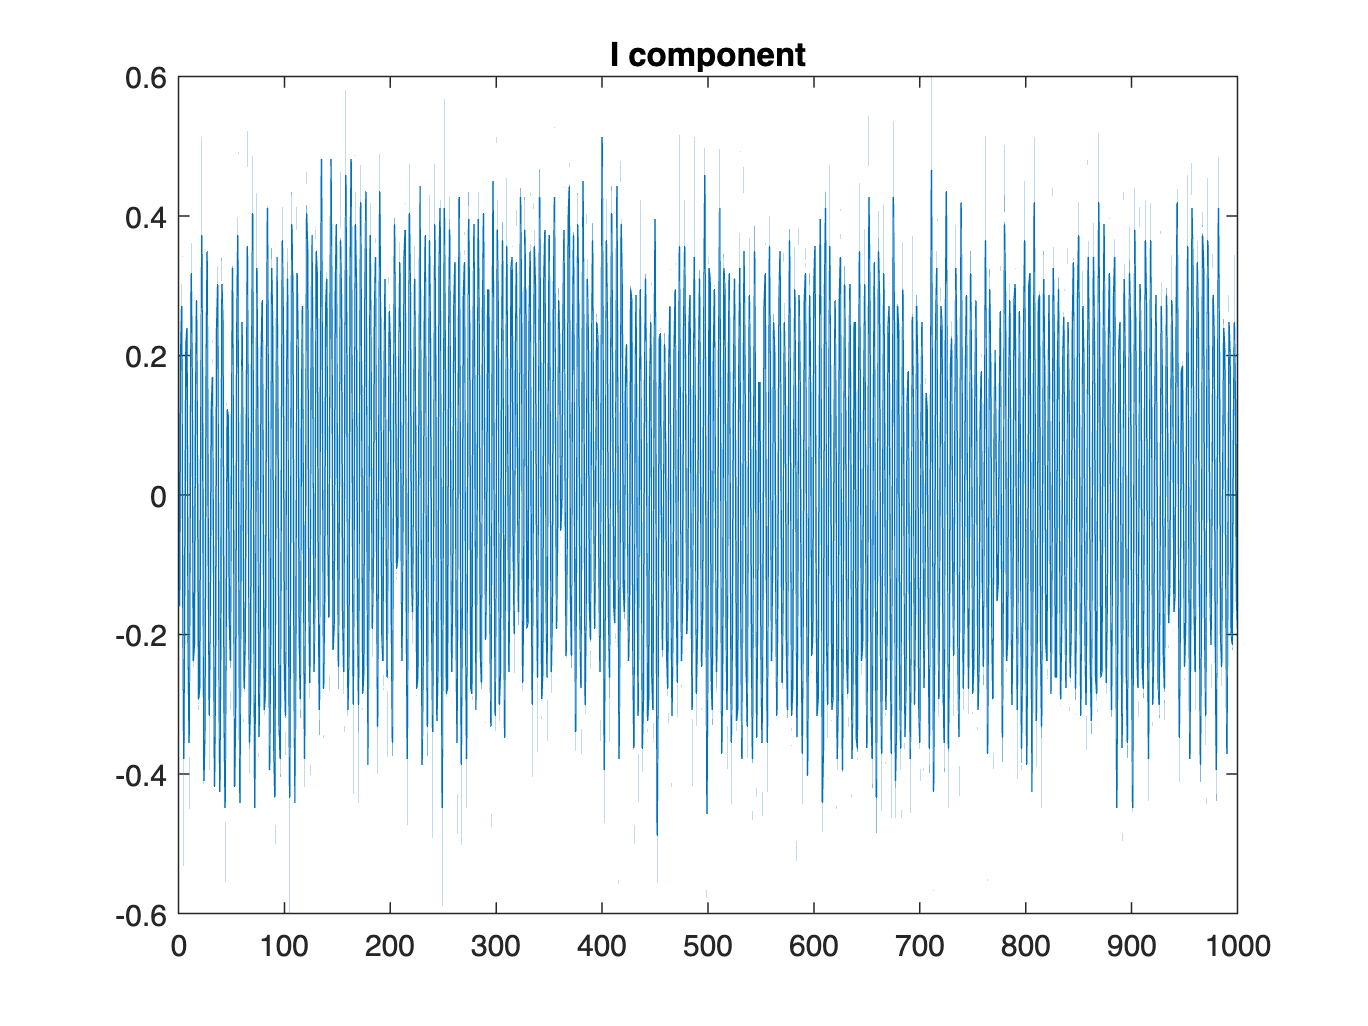

clear;
filename = 'gqrx_20221014_161903_98400000_2400000_fc.raw' ; 
fid = fopen(filename,'rb');
y = fread(fid,'float');
y = y(1:2:end) + 1i*y(2:2:end);
fclose(fid);
n_ = 1:length(y);
plot(real(y(1:1000)')) 
title('I component')

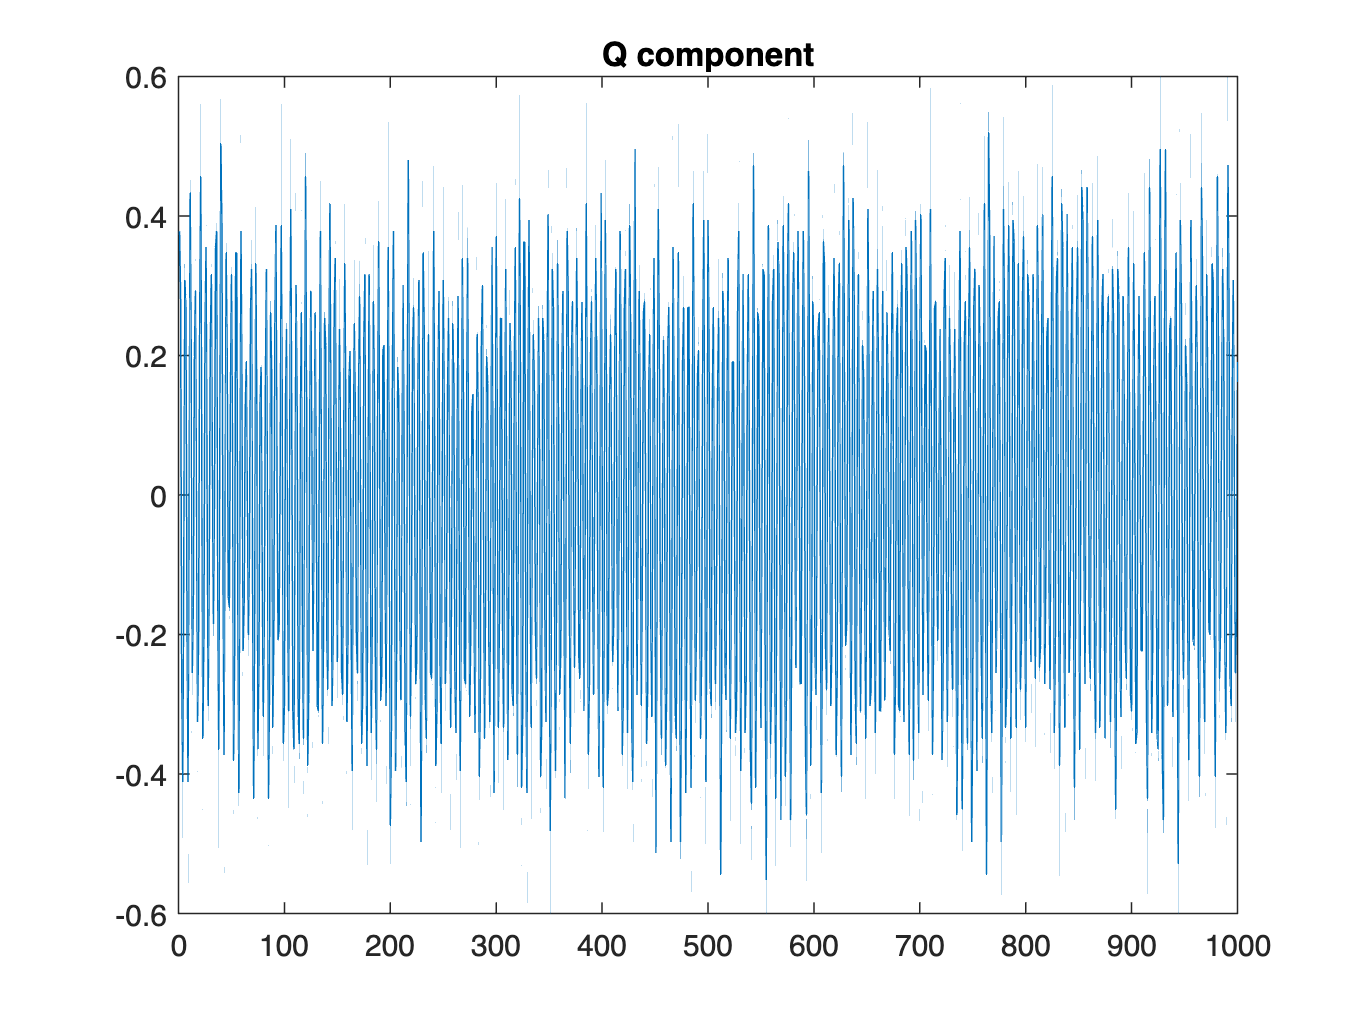

plot(imag(y(1:1000)')) 
title('Q component')

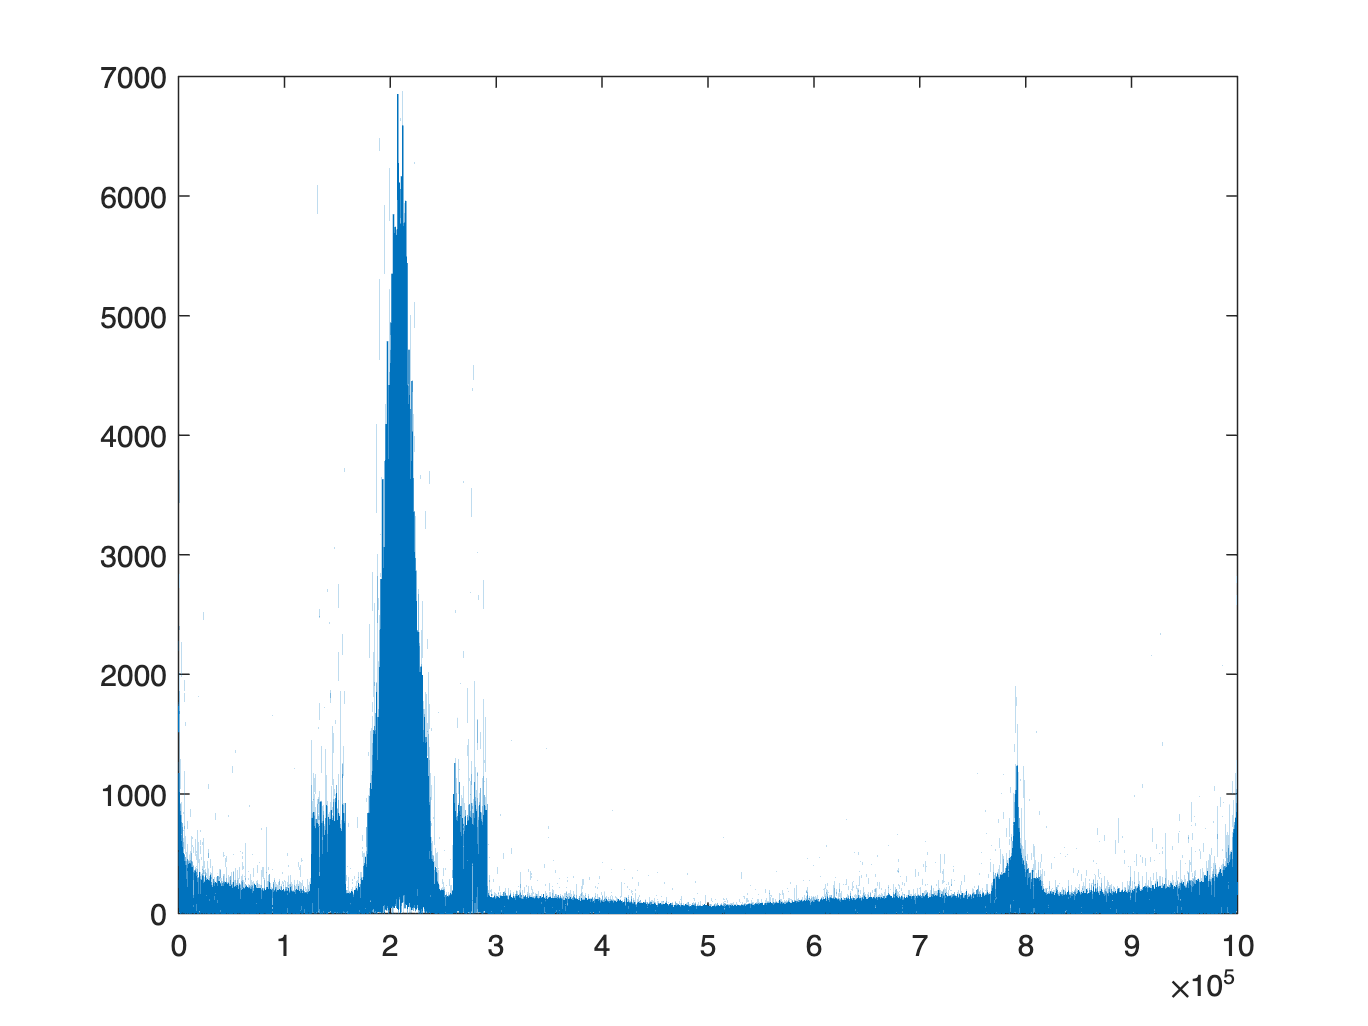

spectrum = fft(y(1:1000000));
plot(abs(spectrum))

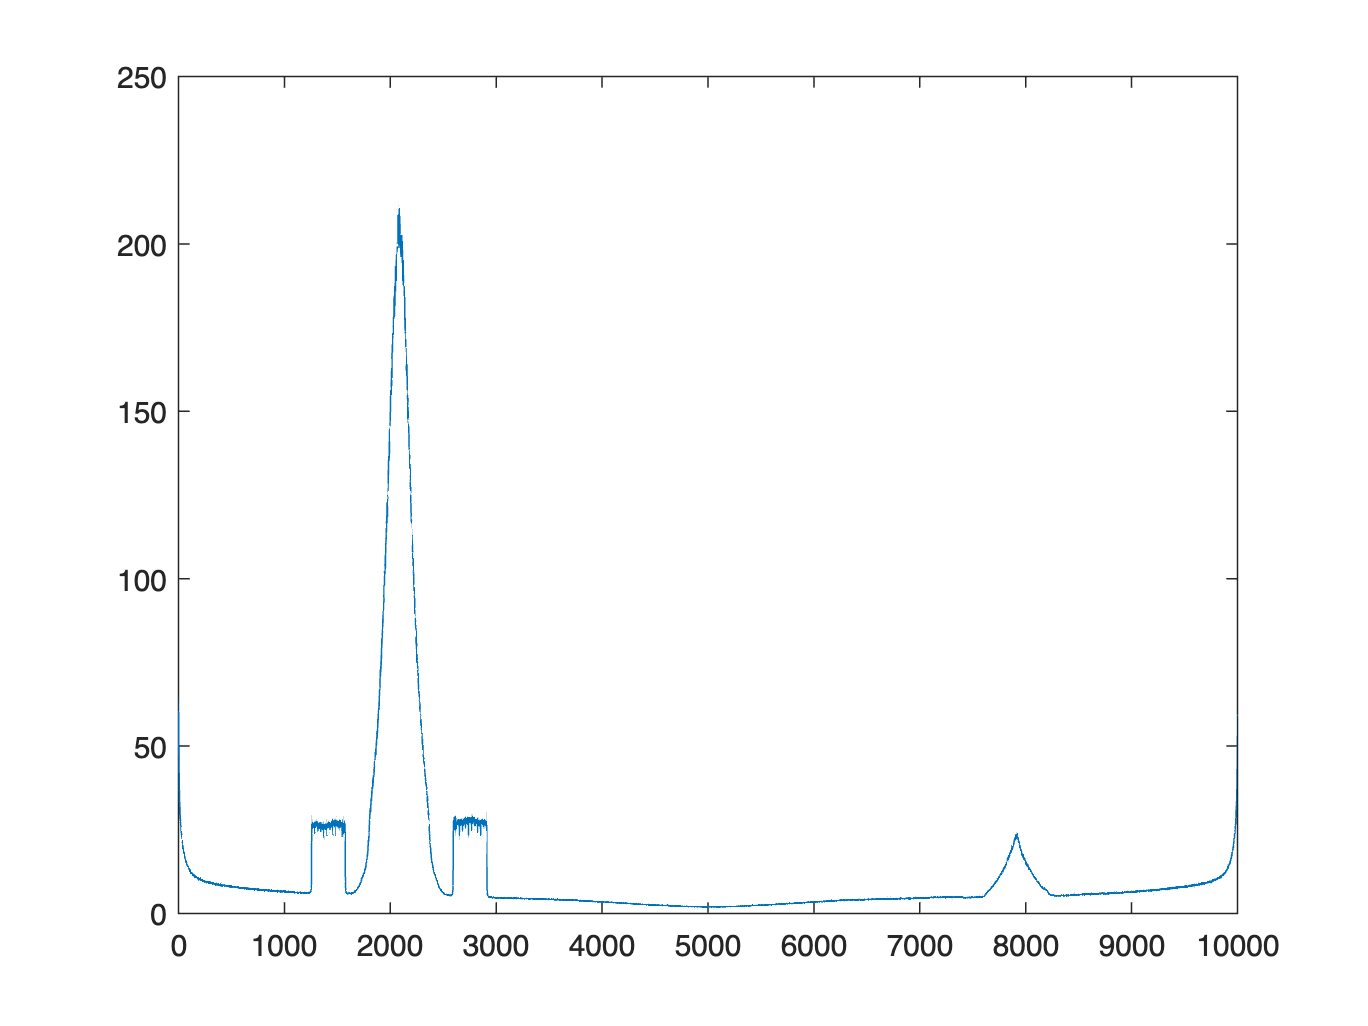

%Magnitude spectrum averaging
delta = 1e4; %Number of points for FFT
a=1; b=delta; i=0;
spec = zeros(delta,1);
while (b<length(y))
    data_segment = y(a:b);
    spec  = (abs(fft(data_segment)))+spec; %accumulator
    a=a+delta;
    b= b+delta;
    i=i+1; %counter
end
plot(spec/i) %plot magnitude average

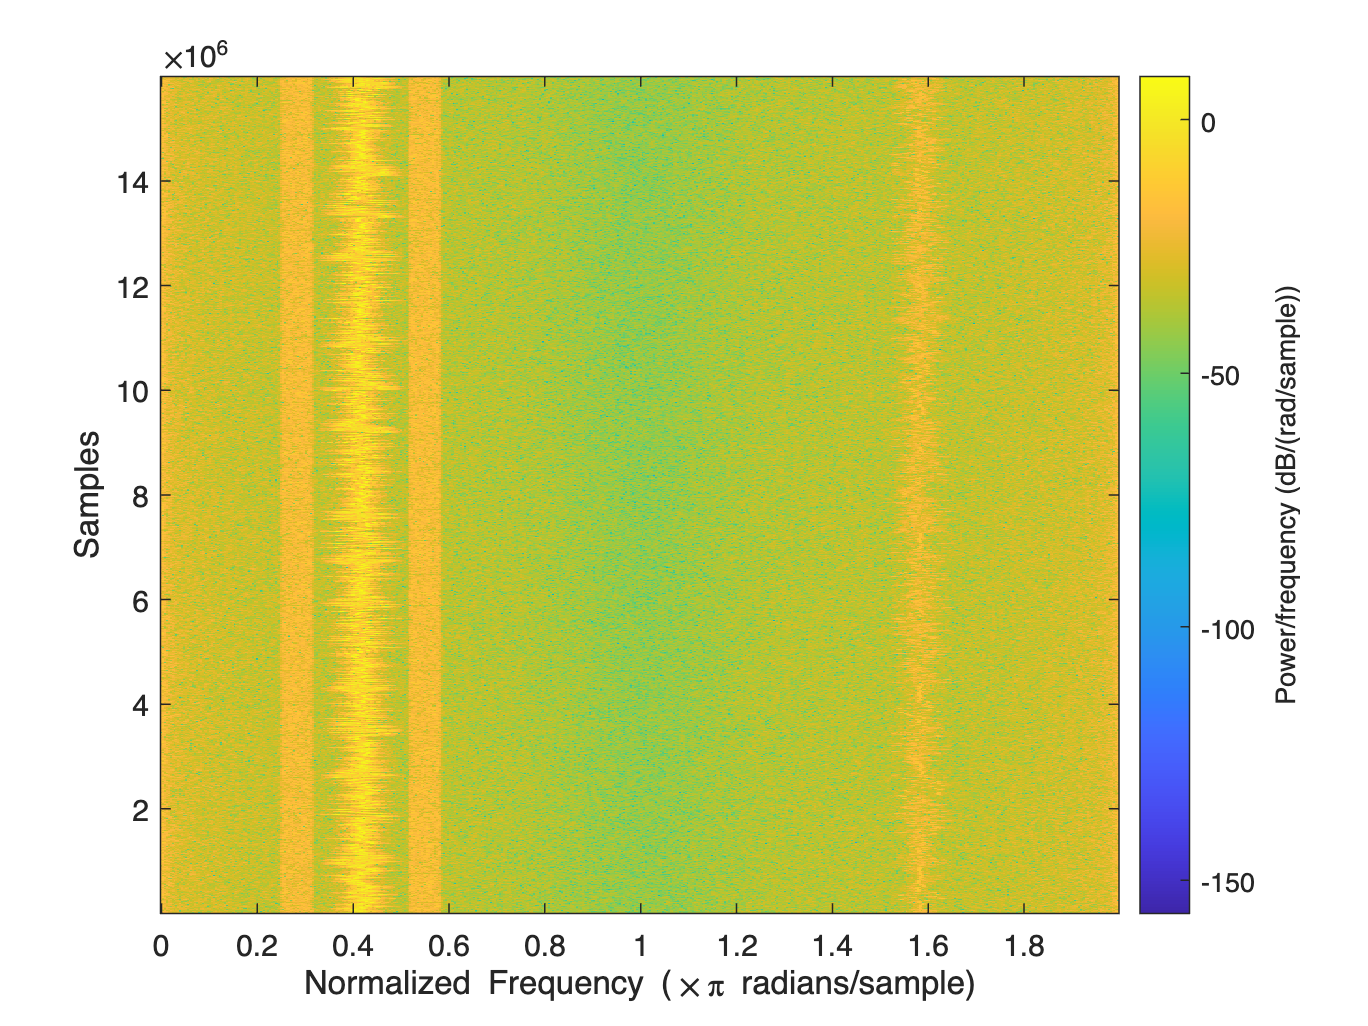

spectrogram(y,500)